## Problem 1: Basic Plant Response Analysis

A) Open-loop Analysis:

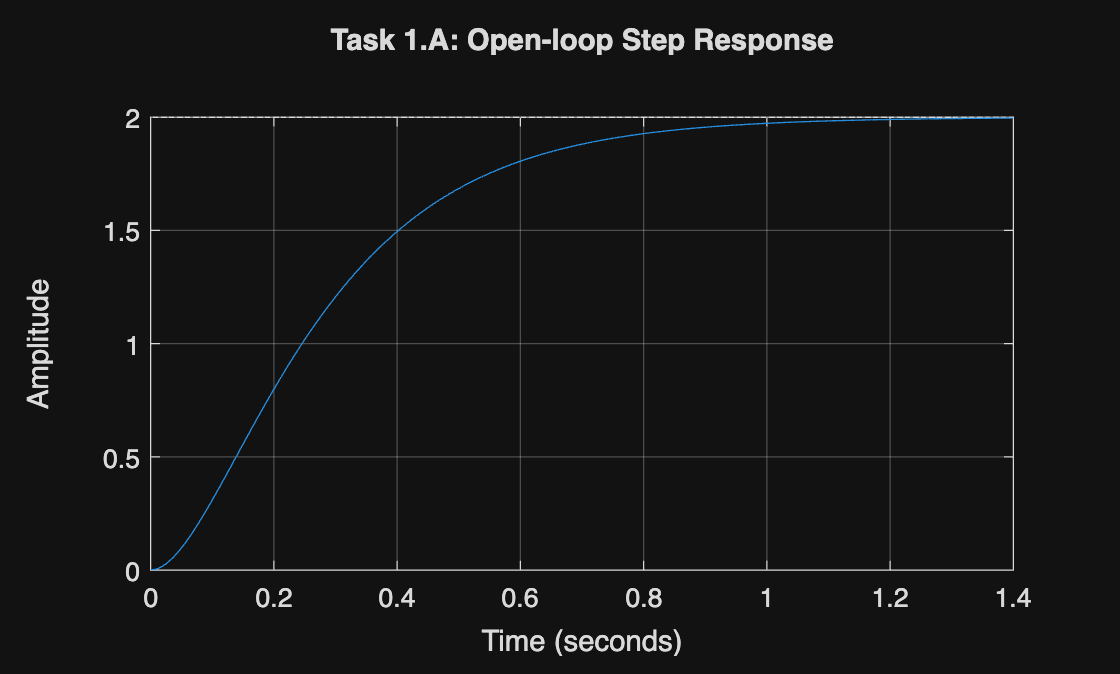

num = 100;
den = [1 15 50];
G = tf(num, den);
figure;
step(G); 
title('Task 1.A: Open-loop Step Response');
grid on;

% Performance Metrics and Steady-State Error
info = stepinfo(G);
fprintf('Rise Time: %.3f s\n', info.RiseTime);

Rise Time: 0.518 s


fprintf('Settling Time: %.3f s\n', info.SettlingTime);

Settling Time: 0.920 s


fprintf('Overshoot: %.2f%%\n', info.Overshoot);

Overshoot: 0.00%


fprintf('Peak: %.3f\n', info.Peak);

Peak: 1.998


fprintf('Steady State Error: %.3f\n', 1 - info.SettlingMax);

Steady State Error: -0.998


B) P Controller Design:

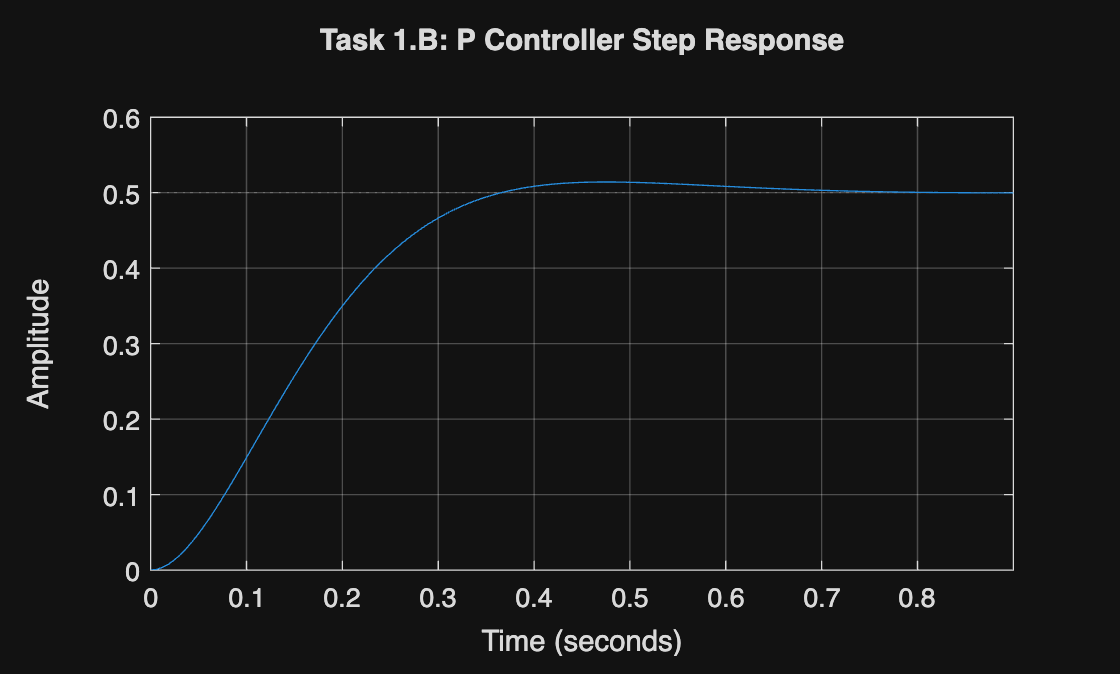

C1 = tf(0.5,1);% Proportional controller
sys_cl = feedback(C1 * G,1);% Closed-loop system
figure;
step(sys_cl);
grid on;
title('Task 1.B: P Controller Step Response');

% Performance Metrics and Steady-State Error
info_cl = stepinfo(sys_cl);
fprintf('Closed-loop Rise Time: %.3f s\n', info_cl.RiseTime);

Closed-loop Rise Time: 0.229 s


fprintf('Closed-loop Settling Time: %.3f s\n', info_cl.SettlingTime);

Closed-loop Settling Time: 0.574 s


fprintf('Closed-loop Overshoot: %.2f%%\n', info_cl.Overshoot);

Closed-loop Overshoot: 2.84%


fprintf('Closed-loop Peak: %.3f\n', info_cl.Peak);

Closed-loop Peak: 0.514



[y,~] = step(sys_cl);
SteadyStateValue = y(end); % Calculate the steady-state value from the step response
fprintf('Closed-loop Steady State Error: %.3f\n', 1 - SteadyStateValue);

Closed-loop Steady State Error: 0.500


With P-only control, the control signal is directly proportional to the error. So for a non-zero control signal, a non-zero error must remain.

C) PI Controller Design:

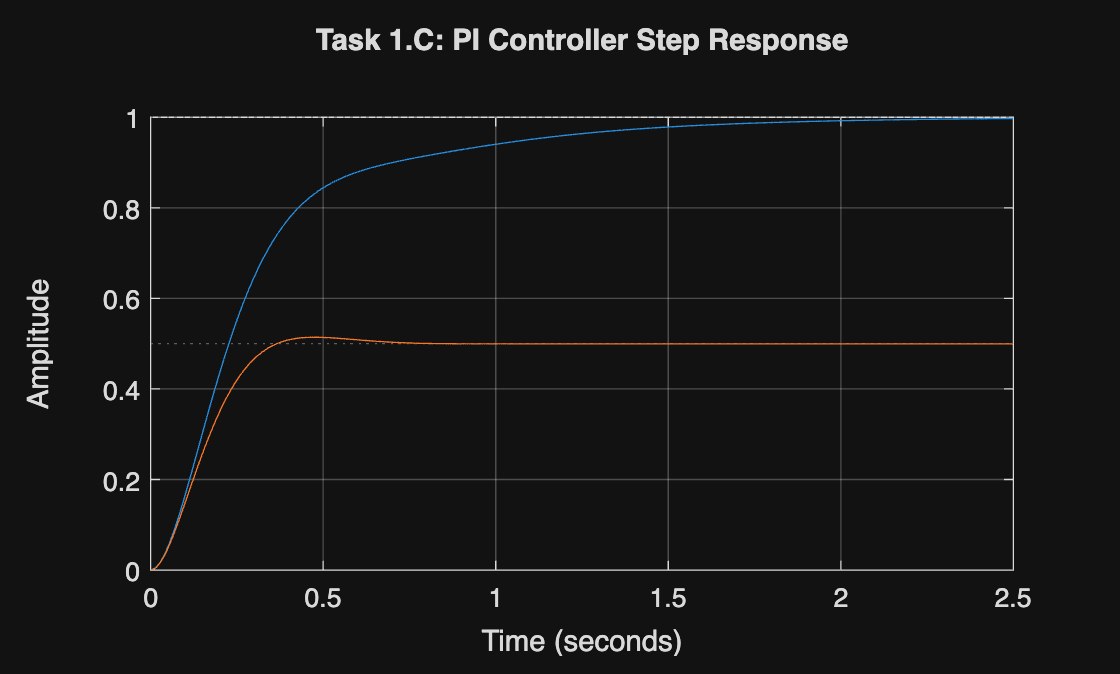

C2 = pid(0.5,1.5,0);% PI controller
sys_cl2 = feedback(C2 * G,1);% Closed-loop system
figure;
step(sys_cl2, sys_cl);% Blue = PI, Red = P control
grid on;
title('Task 1.C: PI Controller Step Response');

% Performance Metrics and Steady-State Error
info_cl2 = stepinfo(sys_cl2);
fprintf('Closed-loop Rise Time: %.3f s\n', info_cl2.RiseTime);

Closed-loop Rise Time: 0.628 s


fprintf('Closed-loop Settling Time: %.3f s\n', info_cl2.SettlingTime);

Closed-loop Settling Time: 1.538 s


fprintf('Closed-loop Overshoot: %.2f%%\n', info_cl2.Overshoot);

Closed-loop Overshoot: 0.00%


fprintf('Closed-loop Peak: %.3f\n', info_cl2.Peak);

Closed-loop Peak: 0.998



[y,~] = step(sys_cl2);
SteadyStateValue = y(end); % Calculate the steady-state value from the step response
fprintf('Closed-loop Steady State Error: %.3f\n', 1 - SteadyStateValue);

Closed-loop Steady State Error: 0.004


The integral control accumulates error with time and keeps on increasing until the error becomes zero. 

D) PID Controller Tuning:

– Overshoot < 10%

– Settling time < 2 seconds

– Zero steady-state error

Tuning PID = in the previous system, added and tuned derivative control by hit and trial method to achieve zero steady state error.

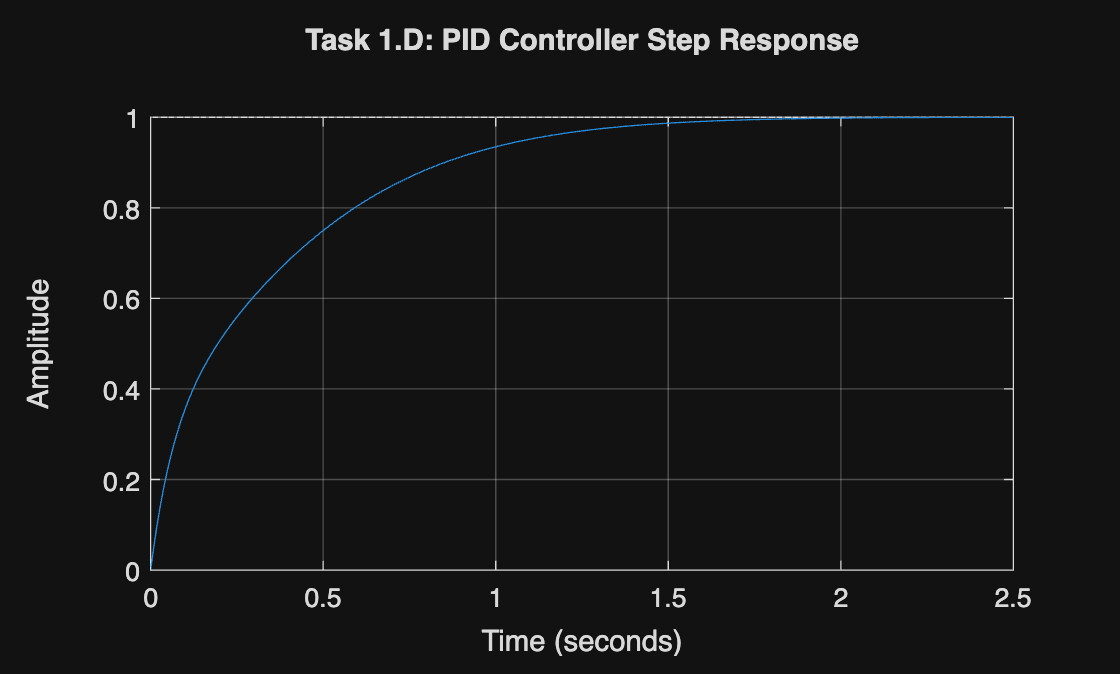

C3 = pid(0.5,1.5,0.06);
sys_cl3 = feedback(C3*G,1);
figure;
step(sys_cl3);
grid on;
title('Task 1.D: PID Controller Step Response');

% Performance Metrics and Steady-State Error
info_cl3 = stepinfo(sys_cl3);
fprintf('Closed-loop Rise Time: %.3f s\n', info_cl3.RiseTime);

Closed-loop Rise Time: 0.833 s


fprintf('Closed-loop Settling Time: %.3f s\n', info_cl3.SettlingTime);

Closed-loop Settling Time: 1.377 s


fprintf('Closed-loop Overshoot: %.2f%%\n', info_cl3.Overshoot);

Closed-loop Overshoot: 0.00%


fprintf('Closed-loop Peak: %.3f\n', info_cl3.Peak);

Closed-loop Peak: 1.000



[y,~] = step(sys_cl3);
SteadyStateValue = y(end); % Calculate the steady-state value from the step response
fprintf('Closed-loop Steady State Error: %.3f\n', 1 - SteadyStateValue);

Closed-loop Steady State Error: 0.000


fprintf('Kp = 0.5, Ki = 1.5, Kd = 0.06');

Kp = 0.5, Ki = 1.5, Kd = 0.06

## Problem 2: Complex Input Tracking

A) Multi-Step Reference:

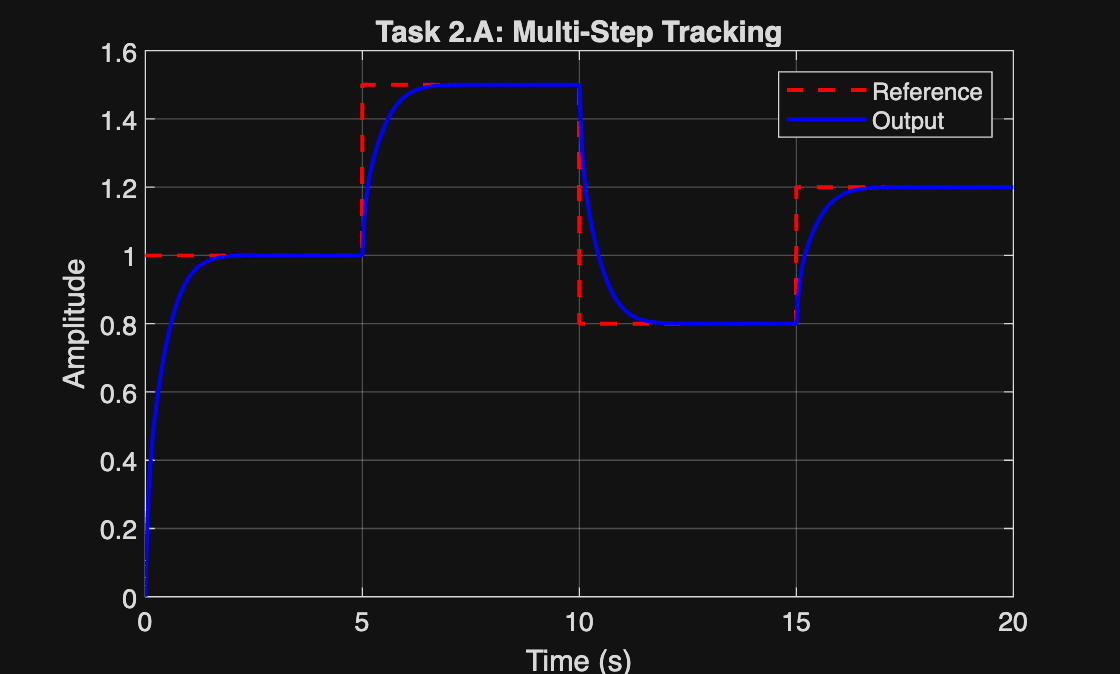

% Multi-Step Reference Signal
t = 0:0.01:20;
r = zeros(size(t));
for i = 1:length(t)
    if t(i) < 5
        r(i) = 1;
    elseif t(i) < 10
        r(i) = 1.5;
    elseif t(i) < 15
        r(i) = 0.8;
    else
        r(i) = 1.2;
    end
end
[y,~] = lsim(sys_cl3,r,t);
figure;
plot(t, r, 'r--', t, y, 'b', 'LineWidth', 1.5); 
legend('Reference', 'Output');
title('Task 2.A: Multi-Step Tracking');
grid on;
xlabel('Time (s)'); 
ylabel('Amplitude');

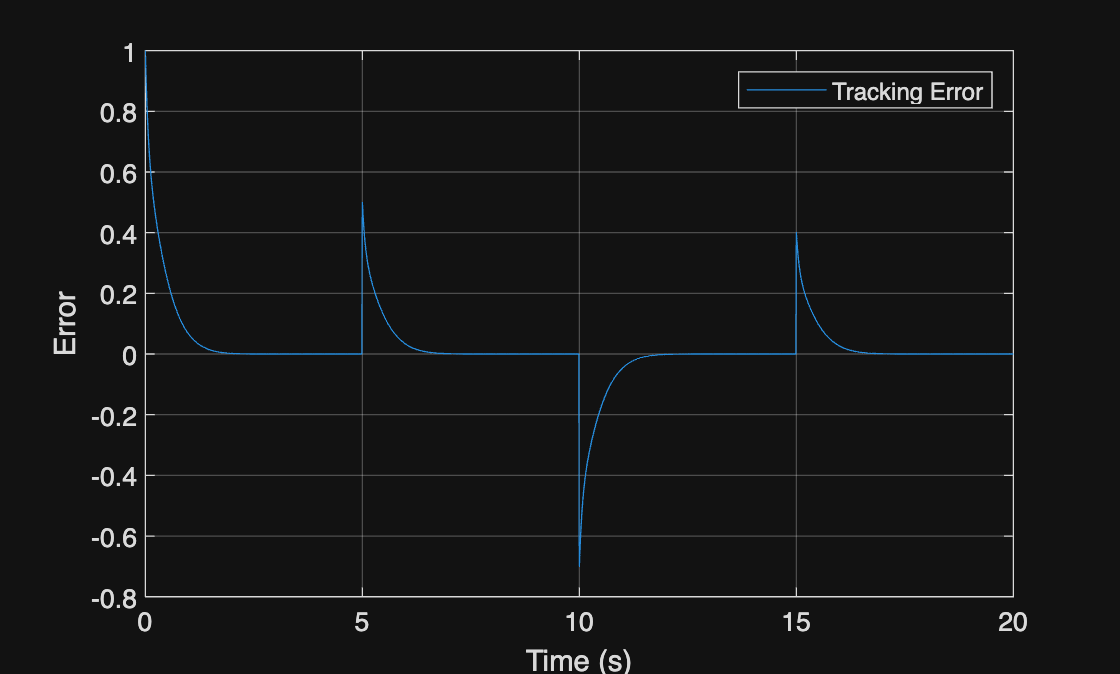


% Calculate the tracking error
error = r(:) - y(:);
figure;
plot(t, error);
xlabel('Time (s)');
ylabel('Error');
grid on;
legend('Tracking Error');

B) Ramp Input:

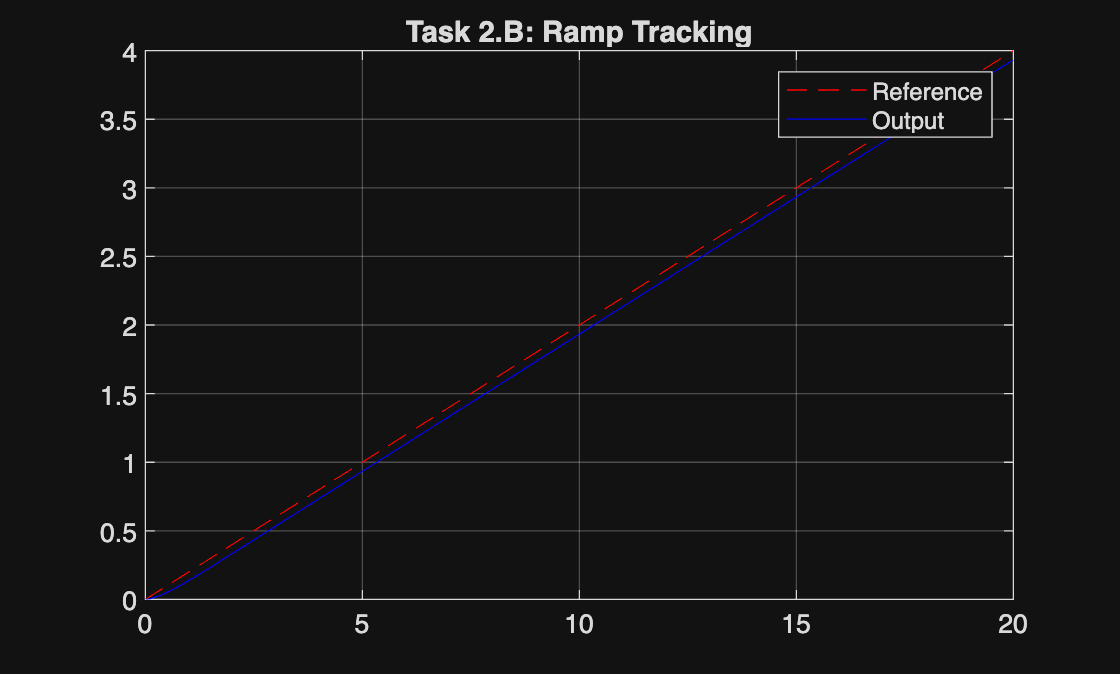

r_ramp = 0.2*t;
[y_ramp,~] = lsim(sys_cl3, r_ramp, t); 
figure;
plot(t, r_ramp, 'r--', t, y_ramp, 'b');
legend('Reference', 'Output');
title('Task 2.B: Ramp Tracking');
grid on;

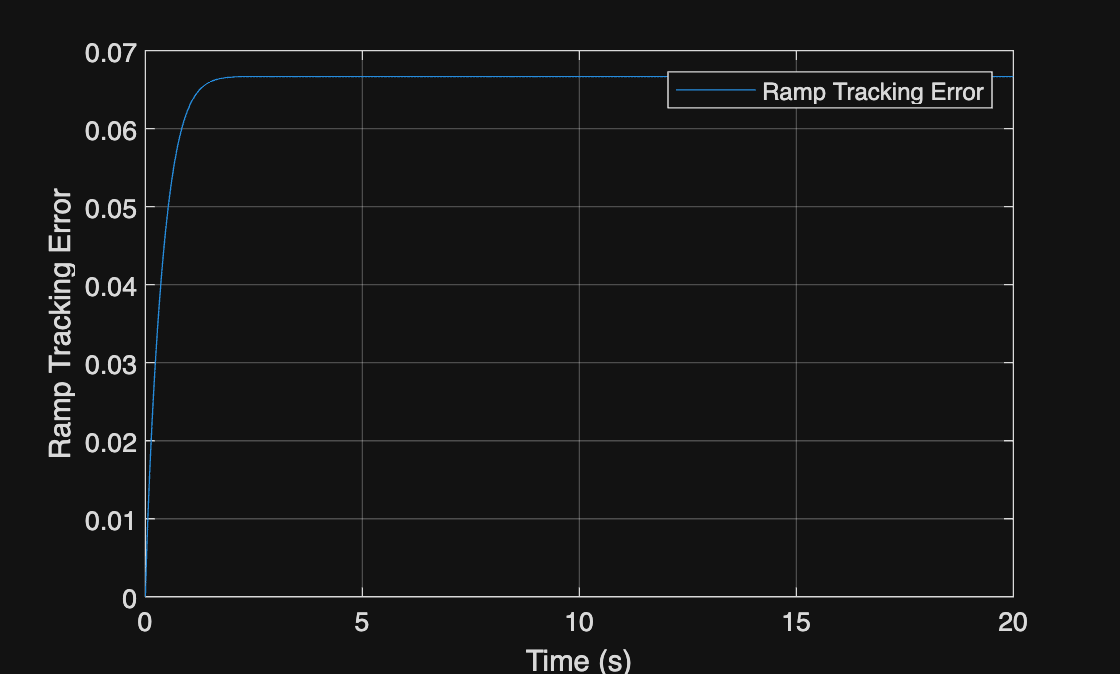

% Calculate the tracking error for the ramp input
error_ramp = r_ramp(:) - y_ramp(:);
figure;
plot(t, error_ramp);
xlabel('Time (s)');
ylabel('Ramp Tracking Error');
grid on;
legend('Ramp Tracking Error');

% Steady State Tracking Error calculation
steadyStateRampError = r_ramp(end) - y_ramp(end); 
fprintf('Steady-State Ramp Error: %.4f\n', steadyStateRampError);

Steady-State Ramp Error: 0.0667


The closed-loop system becomes type-1 because the pid controller add 1 inteegrator. This create a finite constant error for ramp.

C) Sinusoidal Reference:

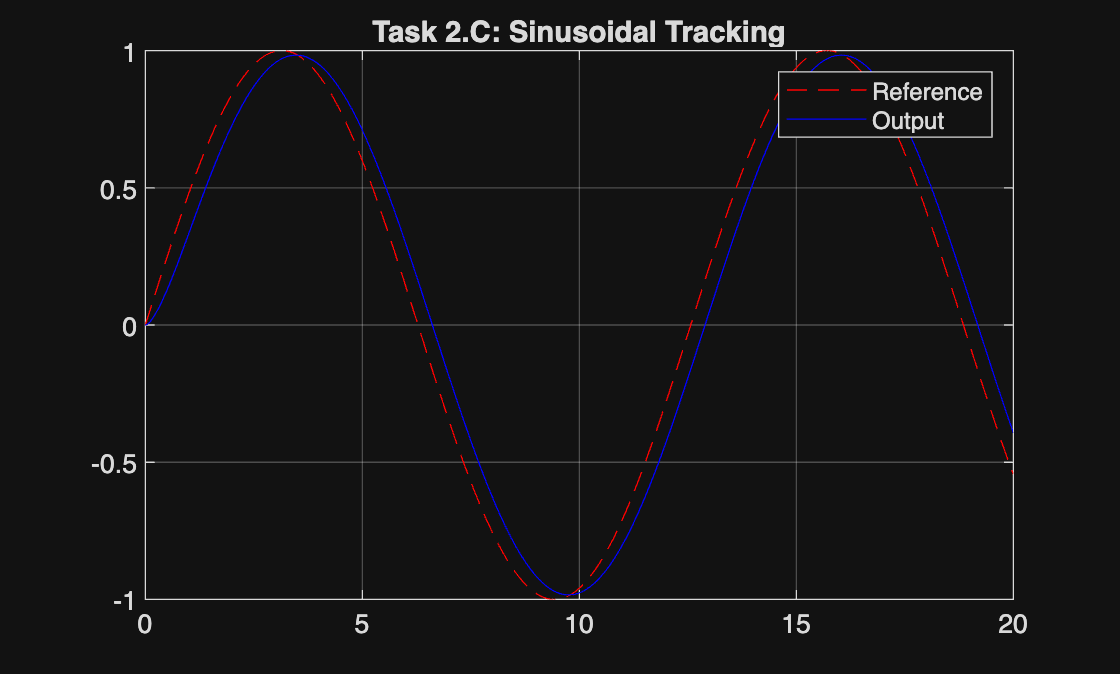

r_sin = sin(0.5*t);
[y_sin, ~] = lsim(sys_cl3, r_sin, t);
figure;
plot(t, r_sin, 'r--', t, y_sin, 'b');
legend('Reference', 'Output');
title('Task 2.C: Sinusoidal Tracking');
grid on;

% search window for the first peak
window = find(t < 5);
% data for just this window
r_window = r_sin(window);
y_window = y_sin(window);
% max value and its index
[peak_r, idx_r] = max(r_window);
[peak_y, idx_y] = max(y_window);
% Convert index to time
t_r = t(idx_r);
t_y = t(idx_y);
t_delay = t_r - t_y;
% phase lag calculation
phase_lag = 0.5 * t_delay * (180/pi);
fprintf('Phase lag  = %.2f degrees\n', phase_lag);

Phase lag  = -9.45 degrees


For sinusoidal inputs, Derivative control is the dominant parameter because it provides the necessary phase lead to reduce tracking delay. While Proportional control helps match the signal's magnitude, Integral control often degrades performance by adding more lag to the system response.

## Problem 3: Practical PID Implementation Challenges

A) Observing Integral Windup (Without Anti-Windup):

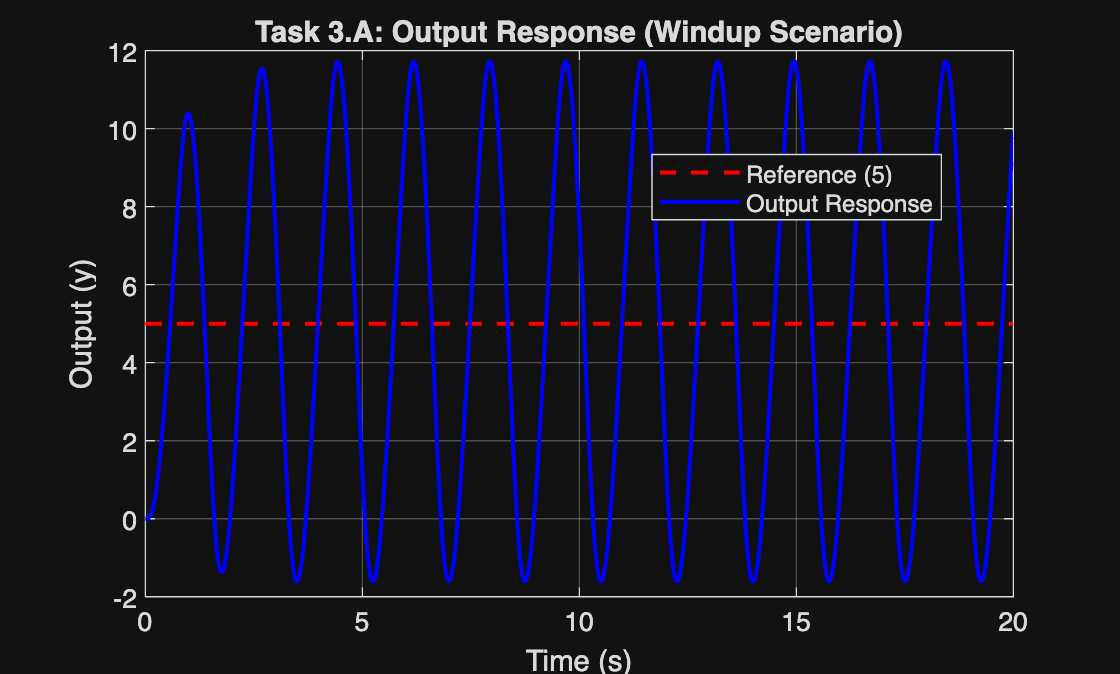

% Transfer Function
G = tf(50,[1 8 25 20]);
% Controller Parameters
Kp = 5;
Ki = 8;
%Simulation Parameters
dt = 0.01;                
t  = 0:dt:20;
N  = length(t);
r = 5 * ones(1, N);% Input Signal
% Actuator Limits
u_max = 10;
u_min = -10;

[A,B,C,D] = ssdata(G);
x = zeros(size(A,1), 1);  
% Pre-allocate arrays for speed
y_no  = zeros(1, N);
u       = zeros(1, N);    
u_sat   = zeros(1, N);    
e       = zeros(1, N);
I_term  = zeros(1, N);
I_error = 0;
% Simulation Loop 
for k = 1:N-1
    y_no(k) = C*x;
    e(k) = r(k) - y_no(k);
    I_error = I_error + e(k)*dt;
    u(k) = Kp*e(k) + Ki*I_error;
    u_sat(k) = max(min(u(k), u_max), u_min);
    I_term(k) = Ki * I_error;
    x = x + dt*(A*x + B*u_sat(k));
end

y_no(end) = C*x;

% Output Response
figure(1);
plot(t, r, 'r--', t, y_no, 'b', 'LineWidth', 1.5); 
grid on; 
xlabel('Time (s)');
ylabel('Output (y)');
title('Task 3.A: Output Response (Windup Scenario)');
legend('Reference (5)', 'Output Response', 'Location', 'best'); 

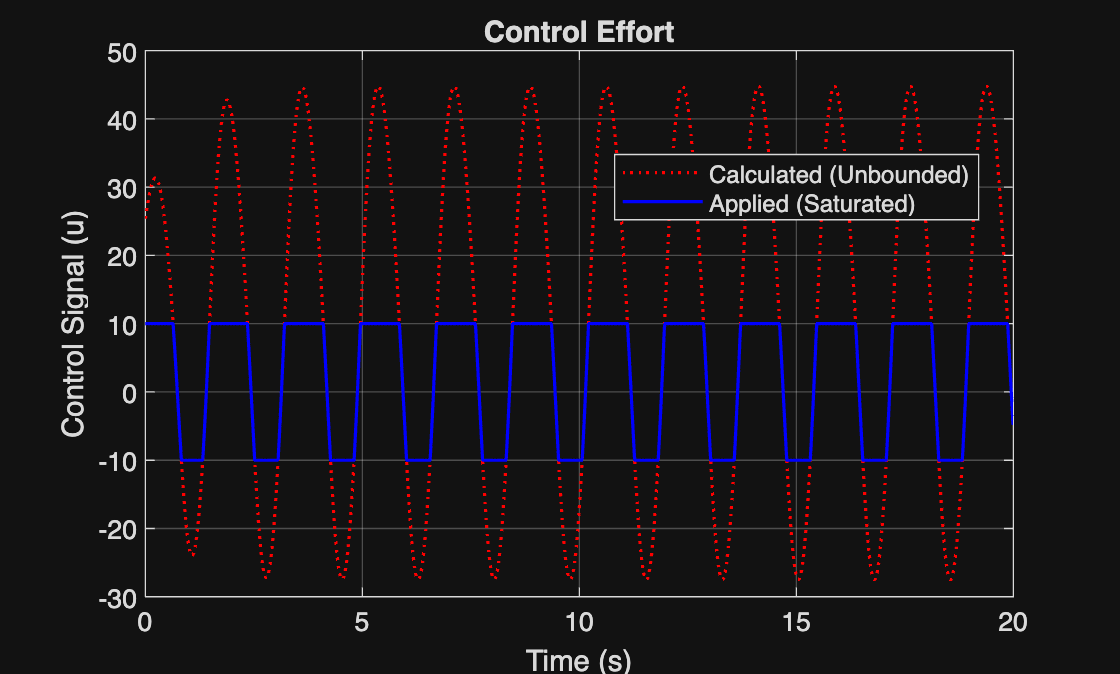

% Control Effort
figure(2);
plot(t, u, 'r:', t, u_sat, 'b', 'LineWidth', 1.2);
grid on;
xlabel('Time (s)');
ylabel('Control Signal (u)');
title('Control Effort');
legend('Calculated (Unbounded)', 'Applied (Saturated)', 'Location', 'best');

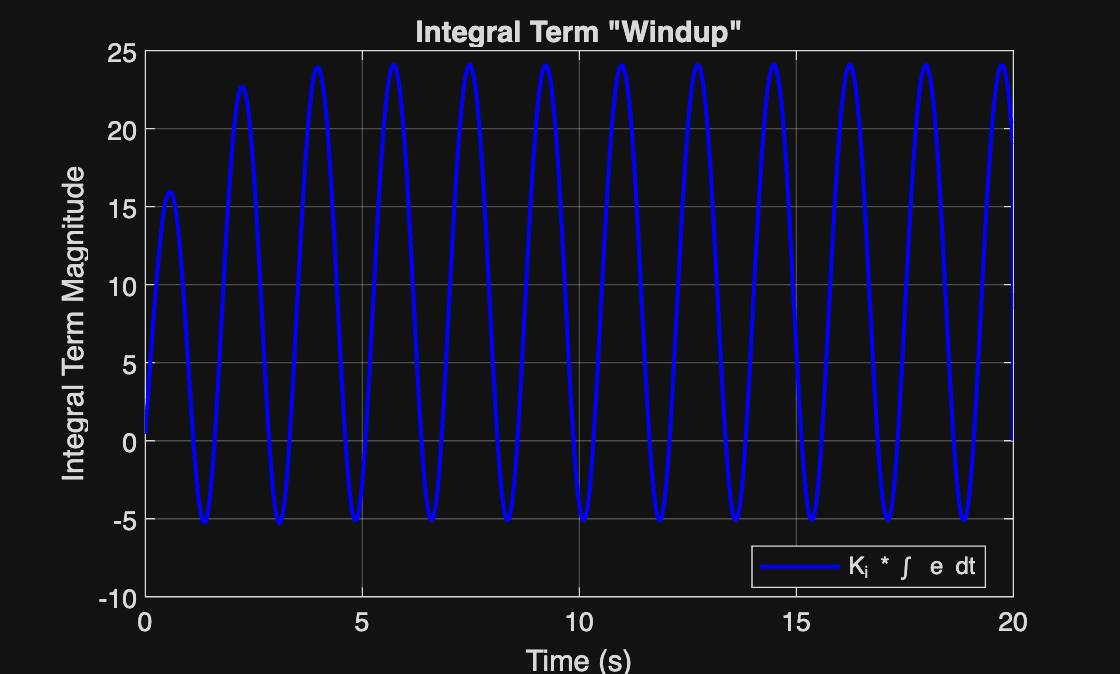

% Integral Term Buildup
figure(3);
plot(t, I_term, 'b', 'LineWidth', 1.5);
grid on;
xlabel('Time (s)');
ylabel('Integral Term Magnitude');
title('Integral Term "Windup"');
legend('K_i * \int e dt', 'Location', 'best');

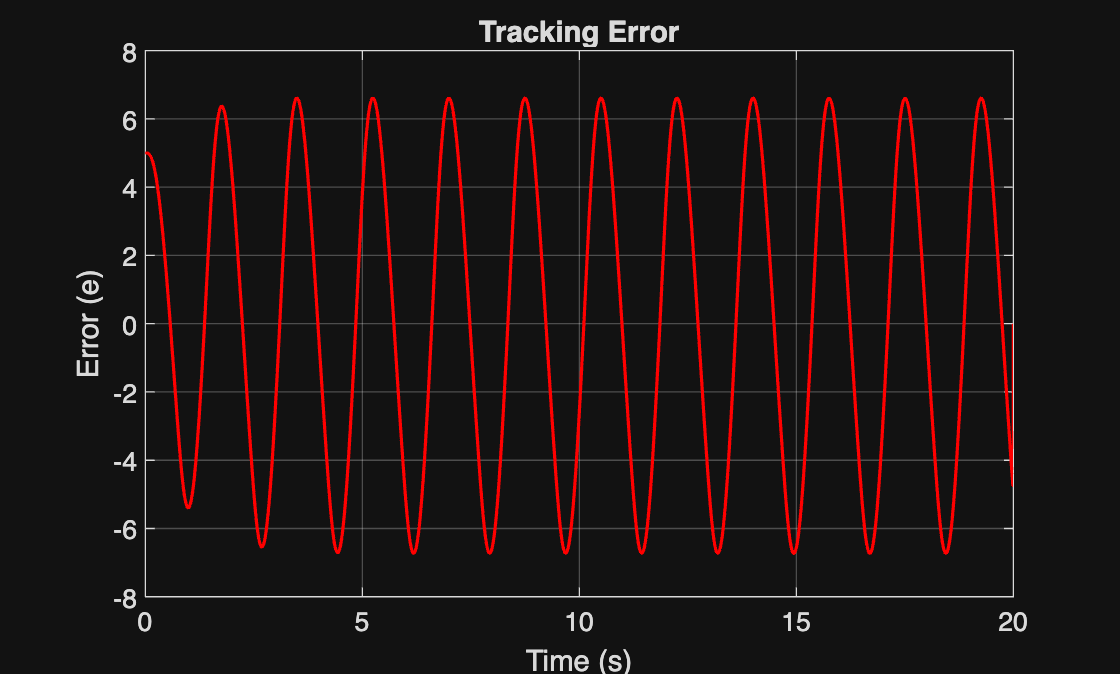

% Error
figure(4);
plot(t, e, 'r', 'LineWidth', 1.2);
grid on;
xlabel('Time (s)');
ylabel('Error (e)');
title('Tracking Error');

Saturation occurs immediately at t = 0 as the control signal (Kp*e = 25) exceeds the actuator limit (u_max = 10)

Even though the actuator is already at its limit, the error is still positive. Because the standard integration logic does not know about the saturation, it keeps adding this error to the total. Thereofore the integral term keeps on increasing.

Although the proportional error decreases as the system nears the setpoint, the integral term remains saturated at a high value. This causes large overshoot. The system cannot settle until the integral term discharges the accumulated error, which introduces oscillations and drastically increases the settling time.

B) Implementing Anti-Windup:

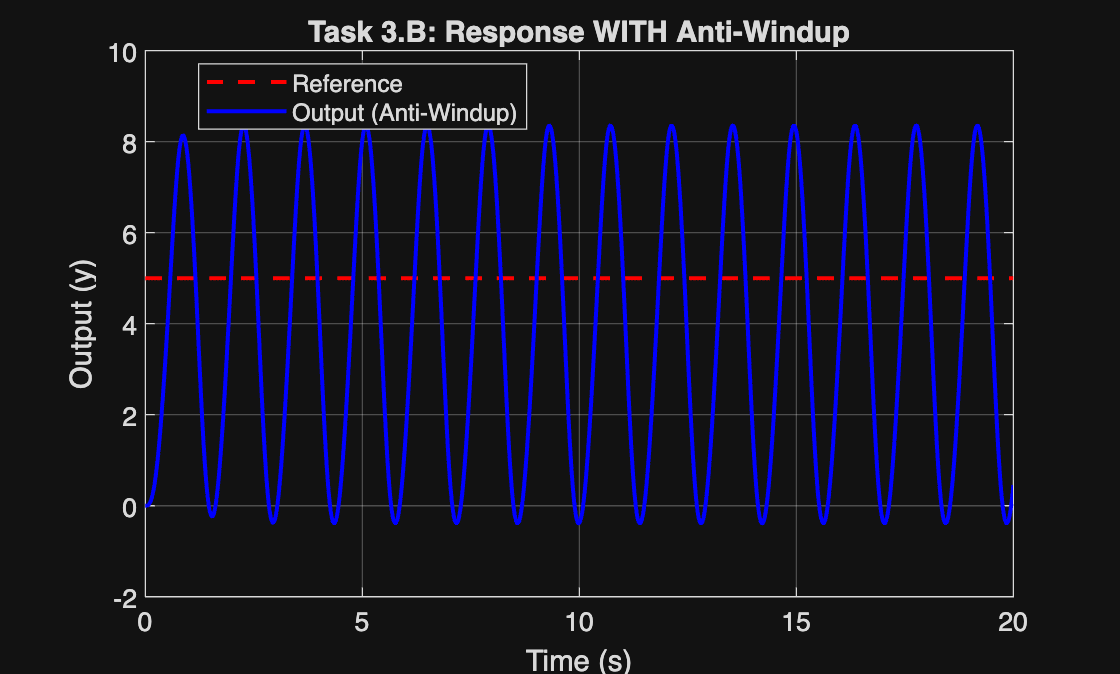

% Controller Parameters
Kp = 5;
Ki = 8;
Kt = sqrt(Ki);
%Simulation Parameters
dt = 0.01;                
t  = 0:dt:20;
N  = length(t);
r = 5 * ones(1, N);% Input Signal
% Actuator Limits
u_max = 10;
u_min = -10;

x = zeros(size(A,1), 1);  
% Pre-allocate arrays for speed
y_aw  = zeros(1, N);
u       = zeros(1, N);    
u_sat_aw   = zeros(1, N);    
e       = zeros(1, N);
I_term  = zeros(1, N);
I_error = 0;
% Simulation Loop
for k = 1:N-1
    y_aw(k) = C*x;
    e(k) = r(k) - y_aw(k); % Error
    u(k) = Kp*e(k) + Ki*I_error;% Unsaturated control
    u_sat_aw(k) = max(min(u(k), u_max), u_min);% Actuator saturation
    I_error = I_error + dt*( e(k) + (1/Kt)*(u_sat_aw(k) - u(k)) );% Ani-Windup back-calculation
    I_term(k) = Ki * I_error;
    x = x + dt*(A*x + B*u_sat_aw(k));
end
y_aw(end) = C * x;
% Output Response (Anti-Windup)
figure;
plot(t, r, 'r--', t, y_aw, 'b', 'LineWidth', 1.5);
grid on;
ylabel('Output (y)');
xlabel('Time (s)');
legend('Reference', 'Output (Anti-Windup)', 'Location', 'best');
title('Task 3.B: Response WITH Anti-Windup');

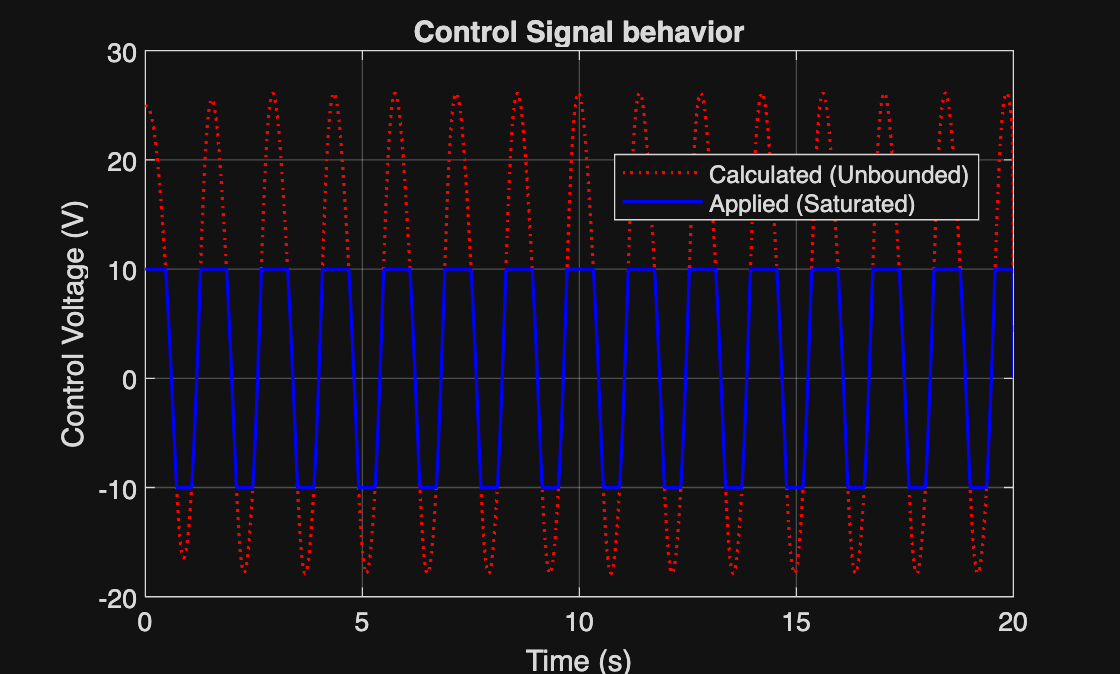

% Control Effort
figure;
plot(t, u, 'r:', t, u_sat_aw, 'b', 'LineWidth', 1.2);
grid on;
ylabel('Control Voltage (V)');
xlabel('Time (s)');
legend('Calculated (Unbounded)', 'Applied (Saturated)', 'Location', 'best');
title('Control Signal behavior');

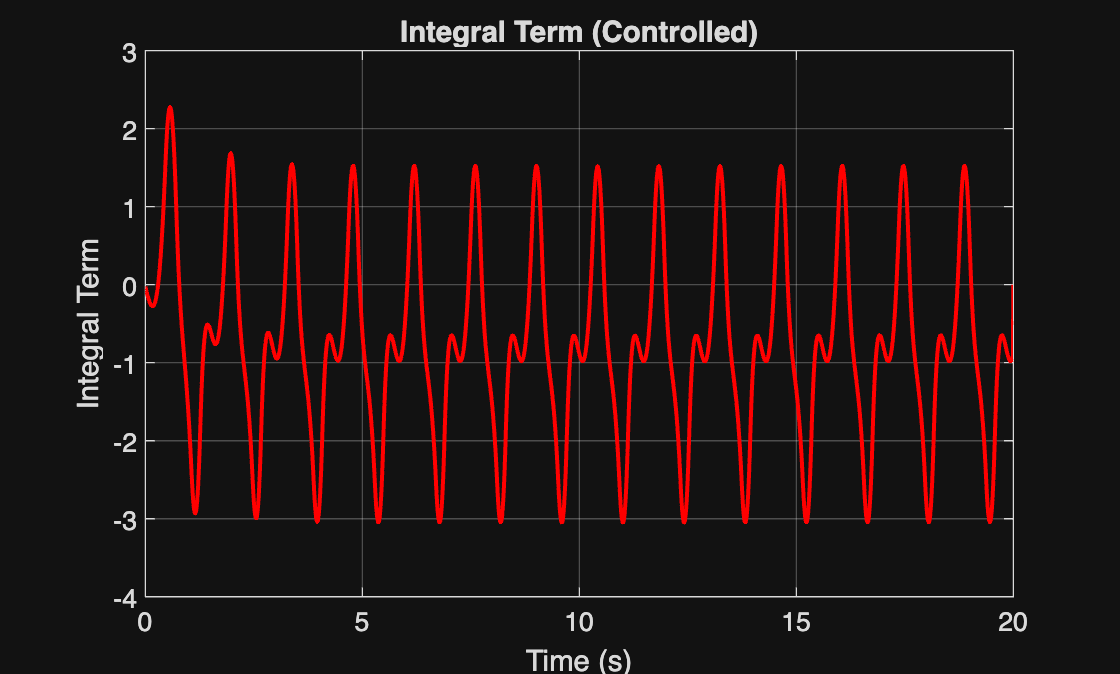

% Integral Term 
figure;
plot(t, I_term, 'r', 'LineWidth', 1.5);
grid on;
ylabel('Integral Term');
xlabel('Time (s)');
title('Integral Term (Controlled)');

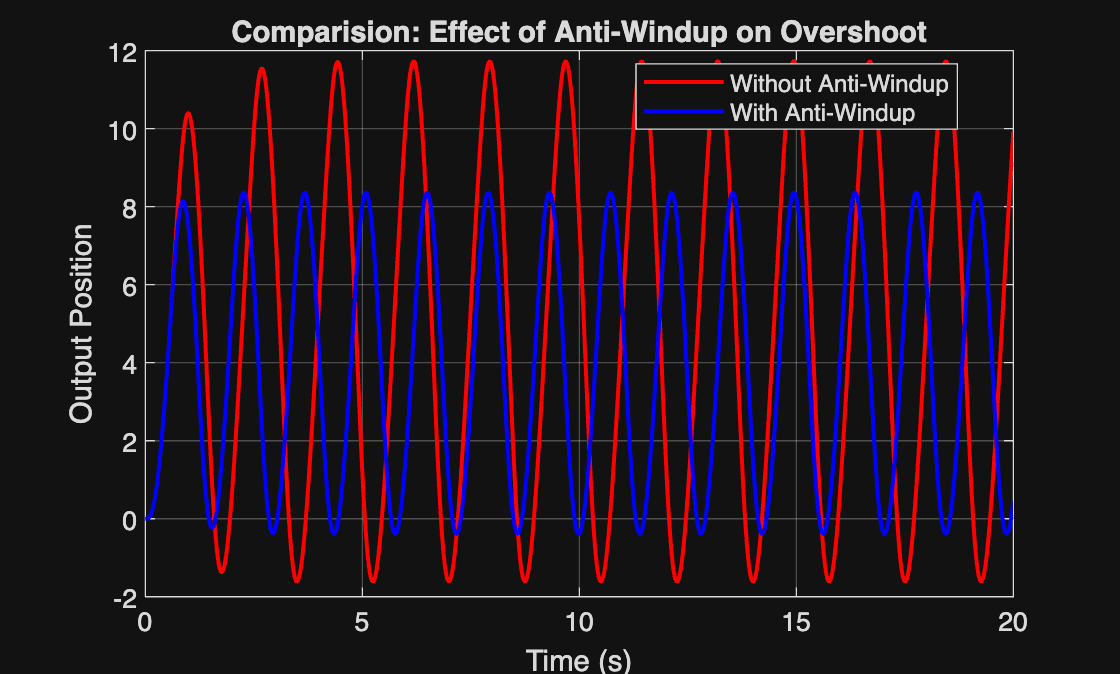

% Comparison 
figure;
plot(t, y_no, 'r', t, y_aw, 'b', 'LineWidth', 1.5);
grid on;
legend('Without Anti-Windup', 'With Anti-Windup', 'Location', 'best');
title('Comparision: Effect of Anti-Windup on Overshoot');
xlabel('Time (s)');
ylabel('Output Position');


% Helper to calculate time spent in saturation 
calc_sat_time = @(u) sum(abs(u) >= 9.99) * dt;
% Metrics for Windup Case
info_windup = stepinfo(y_no, t, 5);
overshoot_w = info_windup.Overshoot;
settling_w  = info_windup.SettlingTime;
sat_time_w  = calc_sat_time(u_sat);
% Metrics for Anti-Windup Case
info_anti = stepinfo(y_aw, t, 5);
overshoot_aw = info_anti.Overshoot;
settling_aw  = info_anti.SettlingTime;
sat_time_aw  = calc_sat_time(u_sat_aw);
% Display Table
ResultsTable = table([overshoot_w; settling_w; sat_time_w], ...
                     [overshoot_aw; settling_aw; sat_time_aw], ...
                     'VariableNames', {'With_Windup', 'With_AntiWindup'}, ...
                     'RowNames', {'Max Overshoot (%)', 'Settling Time (s)', 'Time in Saturation (s)'});
disp(ResultsTable);

                              With_Windup    With_AntiWindup
                              ___________    _______________

    Max Overshoot (%)           134.51           67.167     
    Settling Time (s)              NaN              NaN     
    Time in Saturation (s)       16.41               14     



Anti-windup works by making the integrator 'aware' that the system has hit a wall. Instead of blindly accumulating error when the actuator is maxed out, the controller calculates the excess command signal (u_sat - u) and uses it to cancel out the error input. This prevents the integral value from winding up to impossible levels, ensuring the system can stabilize quickly without a long unwinding delay.

C) Derivative Noise and Low-Pass Filtering:

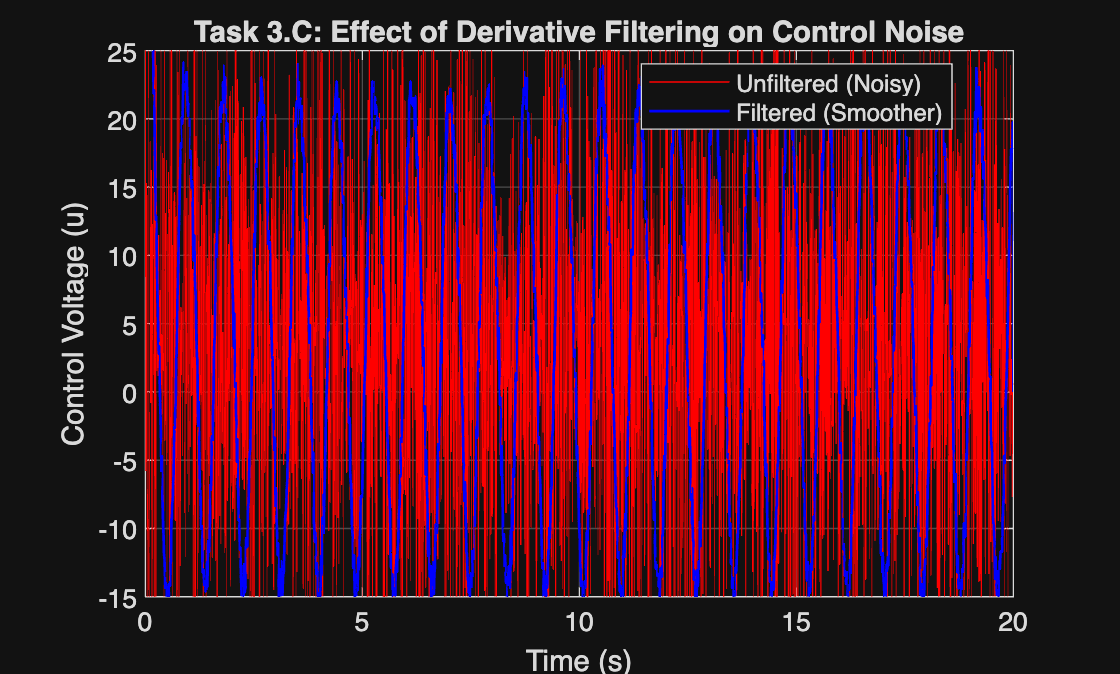

% Controller Parameters
Kp = 5;
Ki = 8;
Kd = 2;
Kt = sqrt(Ki);
% Simulation Parameters
dt = 0.01;                
t  = 0:dt:20;
N  = length(t);
r = 5 * ones(1, N);% Input Signal
% Actuator Limits
u_max = 10;
u_min = -10;
noise_std = 0.05;
% Filter Design
wc = 7;
alpha = exp(-wc * dt);
% Initialization

% Unfiltered Derivative
x_unfilt = zeros(size(A,1), 1);
I_unfilt = 0;
y_unfilt = zeros(1, N);
u_unfilt = zeros(1, N);  % Calculated Control (Noisy)
u_sat_u  = zeros(1, N);  % Applied Control
e_unfilt = zeros(1, N);
e_prev   = 0;
% Filtered Derivative
x_filt   = zeros(size(A,1), 1);
I_filt   = 0;
y_filt   = zeros(1, N);
u_filt   = zeros(1, N);  % Calculated Control (Smoother)
u_sat_f  = zeros(1, N);  % Applied Control
e_filt   = zeros(1, N);

ef_val   = 0;           % Current filtered error value
ef_prev  = 0;           % Previous filtered error value

% Simulation Loop
for k = 1:N-1
    % Generate Noise
    noise_u = noise_std * randn;
    noise_f = noise_std * randn;
% Unfiltered Derivative
    y_unfilt(k) = C * x_unfilt;
    y_meas_u = y_unfilt(k) + noise_u;   % Add noise to measurement
    e_unfilt(k) = r(k) - y_meas_u;
    % Raw Finite Difference Derivative (Amplifies Noise)
    de_raw = (e_unfilt(k) - e_prev) / dt;
    % PID Calculation
    u_unfilt(k) = Kp*e_unfilt(k) + Ki*I_unfilt + Kd*de_raw;
    u_sat_u(k)  = max(min(u_unfilt(k), u_max), u_min);
    % Anti-Windup Integration
    I_unfilt = I_unfilt + dt * (e_unfilt(k) + (1/Kt)*(u_sat_u(k) - u_unfilt(k)));
    % Plant Update
    x_unfilt = x_unfilt + dt * (A*x_unfilt + B*u_sat_u(k));
% Filtered Derivative
    y_filt(k) = C * x_filt;
    y_meas_f = y_filt(k) + noise_f;
    e_filt(k) = r(k) - y_meas_f;
    % Apply Low-Pass Filter to Error Signal
    ef_val = alpha*ef_prev + (1-alpha)*e_filt(k);
    % Derivative of Filtered Error
    de_filt = (ef_val - ef_prev) / dt;
    % PID Calculation
    u_filt(k) = Kp*e_filt(k) + Ki*I_filt + Kd*de_filt;
    u_sat_f(k) = max(min(u_filt(k), u_max), u_min);
    % Anti-Windup Integration
    I_filt = I_filt + dt * (e_filt(k) + (1/Kt)*(u_sat_f(k) - u_filt(k)));
    % Plant Update
    x_filt = x_filt + dt * (A*x_filt + B*u_sat_f(k));
    % Update Previous Values
    e_prev = e_unfilt(k);
    ef_prev = ef_val;
end
% Final Update
y_unfilt(N) = C * x_unfilt;
y_filt(N)   = C * x_filt;
% Control Signal Noise Comparison
figure;
plot(t, u_unfilt, 'r', 'LineWidth', 0.5); hold on;
plot(t, u_filt, 'b', 'LineWidth', 1.0);
grid on;
legend('Unfiltered (Noisy)', 'Filtered (Smoother)', 'Location', 'best');
title('Task 3.C: Effect of Derivative Filtering on Control Noise');
ylabel('Control Voltage (u)');
xlabel('Time (s)');
ylim([-15 25]); 

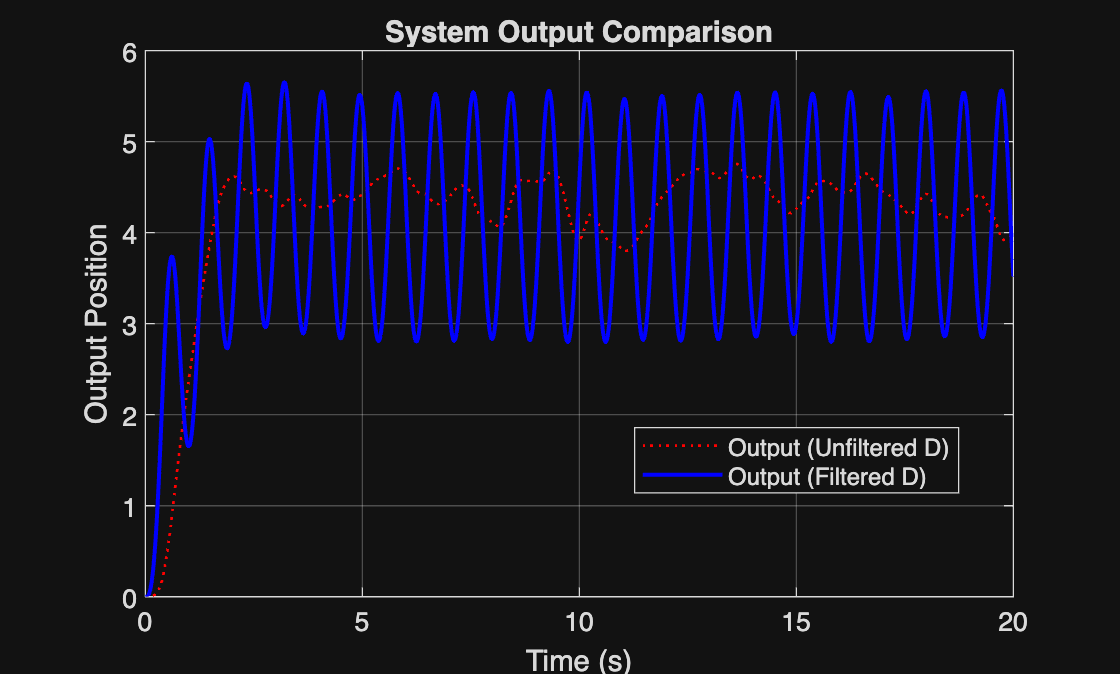

% Output Response Comparison
figure;
plot(t, y_unfilt, 'r:', 'LineWidth', 1.0); hold on;
plot(t, y_filt, 'b', 'LineWidth', 1.5);
grid on;
legend('Output (Unfiltered D)', 'Output (Filtered D)', 'Location', 'best');
title('System Output Comparison');
ylabel('Output Position');
xlabel('Time (s)');

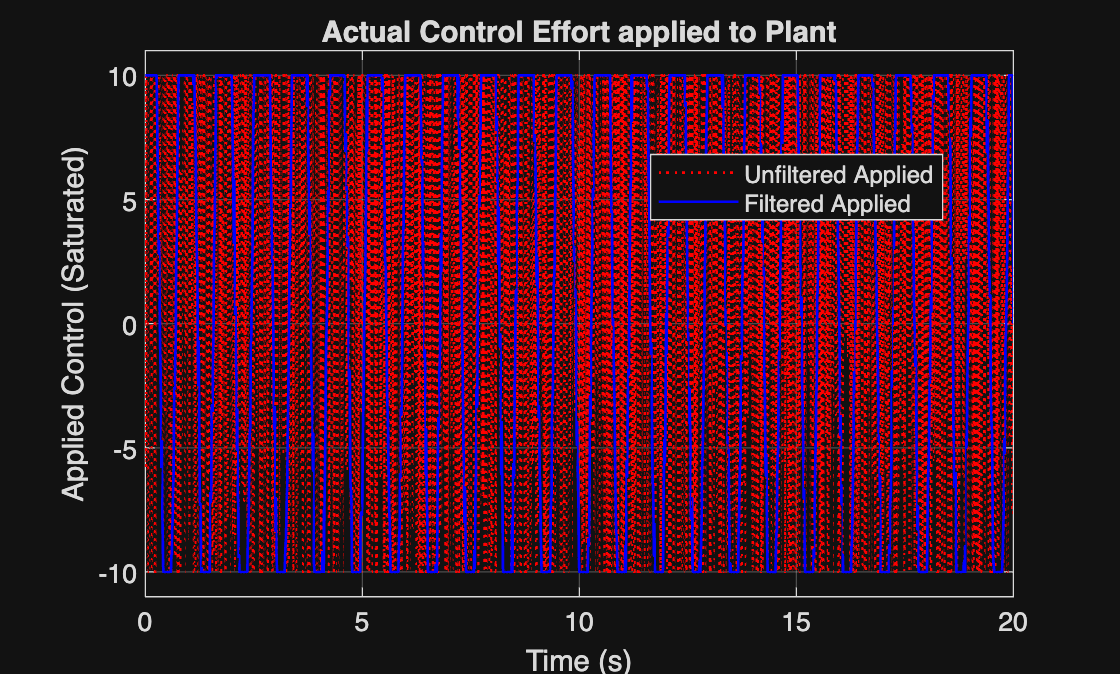

% Saturated (Applied) Control 
figure;
plot(t, u_sat_u, 'r:', 'LineWidth', 1.0); hold on;
plot(t, u_sat_f, 'b', 'LineWidth', 1.0);
grid on;
ylabel('Applied Control (Saturated)');
xlabel('Time (s)');
legend('Unfiltered Applied', 'Filtered Applied', 'Location', 'best');
title('Actual Control Effort applied to Plant');
ylim([-11 11]);

% Metrics
std_u_unfiltered = std(u_unfilt);
std_u_filtered   = std(u_filt);
fprintf('--------------------------------------------------\n');

--------------------------------------------------


fprintf('Noise Reduction Analysis:\n');

Noise Reduction Analysis:


fprintf('Std Dev of Control (Unfiltered): %.4f V\n', std_u_unfiltered);

Std Dev of Control (Unfiltered): 26.9242 V


fprintf('Std Dev of Control (Filtered)  : %.4f V\n', std_u_filtered);

Std Dev of Control (Filtered)  : 13.8125 V


fprintf('--------------------------------------------------\n');

--------------------------------------------------


By cutting off frequencies above a certain threshold (wc), it prevents the derivative from amplifying the high-speed jitter, hence reducing the noise. Moreover since the overshoot happens at frequencies below that threshold, the derivative still detects the slope of the error and applies the braking force (damping) effectively.

D) Complex Trajectory Tracking:

% Controller Parameters
Kp = 5;
Ki = 8;
Kd = 2;
Kt = sqrt(Ki);          
% Simulation Setup
dt = 0.01;              
t  = 0:dt:20;
N  = length(t);
% Actuator Limits
u_max = 10;
u_min = -10;
% Generate Complex Reference Trajectory 
r = zeros(1, N);
for i = 1:N
    ti = t(i);
    if ti < 2
        r(i) = 0.5 * ti;                % Ramp Up
    elseif ti < 4
        r(i) = 1;                       % Hold
    elseif ti < 8
        r(i) = 1 + 0.5*sin(2*pi*(ti-4)); % Sine Wave
    elseif ti < 10
        r(i) = 2;                       % Large Step
    elseif ti < 15
        r(i) = 2 - 0.3*(ti-10);         % Ramp Down
    else
        r(i) = 0.5;                     % Final Hold
    end
end
% Filter Design (Low Pass for Derivative)
wc = 7;                 % Cutoff frequency
alpha = exp(-wc * dt);  % Discrete filter coefficient
% Initialization
x = zeros(size(A,1), 1);
I_term = 0;
y_out = zeros(1, N);
u_log = zeros(1, N);     
e_log = zeros(1, N);     
% Filter Variables
ef_curr = 0;
ef_prev = 0;
% Simulation Loop
for k = 1:N-1
    y_out(k) = C * x; % Measurement 
    e = r(k) - y_out(k); % Error Calculation    
    ef_curr = alpha * ef_prev + (1 - alpha) * e; % Apply Low-Pass Filter to Error        
    u_d = Kd * (ef_curr - ef_prev) / dt; % Derivative Term 
    % PID Calculation
    u_p = Kp * e;
    u_i = Ki * I_term;    
    u_total = u_p + u_i + u_d;     
    u_sat = max(min(u_total, u_max), u_min); % Saturation   
    I_term = I_term + dt * (e + (1/Kt)*(u_sat - u_total)); % Anti-Windup Integration  
    x = x + dt * (A*x + B*u_sat); % Plant Update
    
    u_log(k) = u_sat;
    e_log(k) = e;
    ef_prev = ef_curr;
end
% Final Update
y_out(N) = C * x;
e_log(N) = r(N) - y_out(N);
% Performance Metrics
rms_error = sqrt(mean(e_log.^2));
fprintf('--------------------------------------\n');

--------------------------------------


fprintf('Task 3.D Performance:\n');

Task 3.D Performance:


fprintf('RMS Tracking Error: %.4f\n', rms_error);

RMS Tracking Error: 1.0663


fprintf('--------------------------------------\n');

--------------------------------------


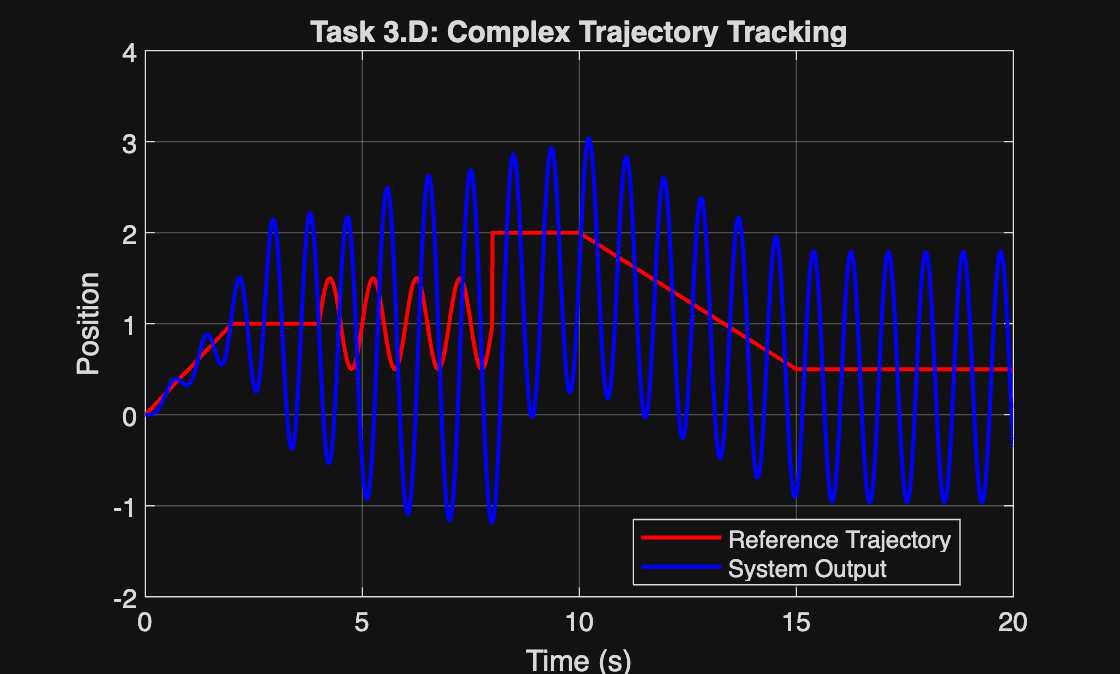

% Tracking Performance 
figure;
plot(t, r, 'r', 'LineWidth', 1.5); hold on;
plot(t, y_out, 'b', 'LineWidth', 1.5);
grid on;
title('Task 3.D: Complex Trajectory Tracking');
legend('Reference Trajectory', 'System Output', 'Location', 'best');
xlabel('Time (s)');
ylabel('Position');

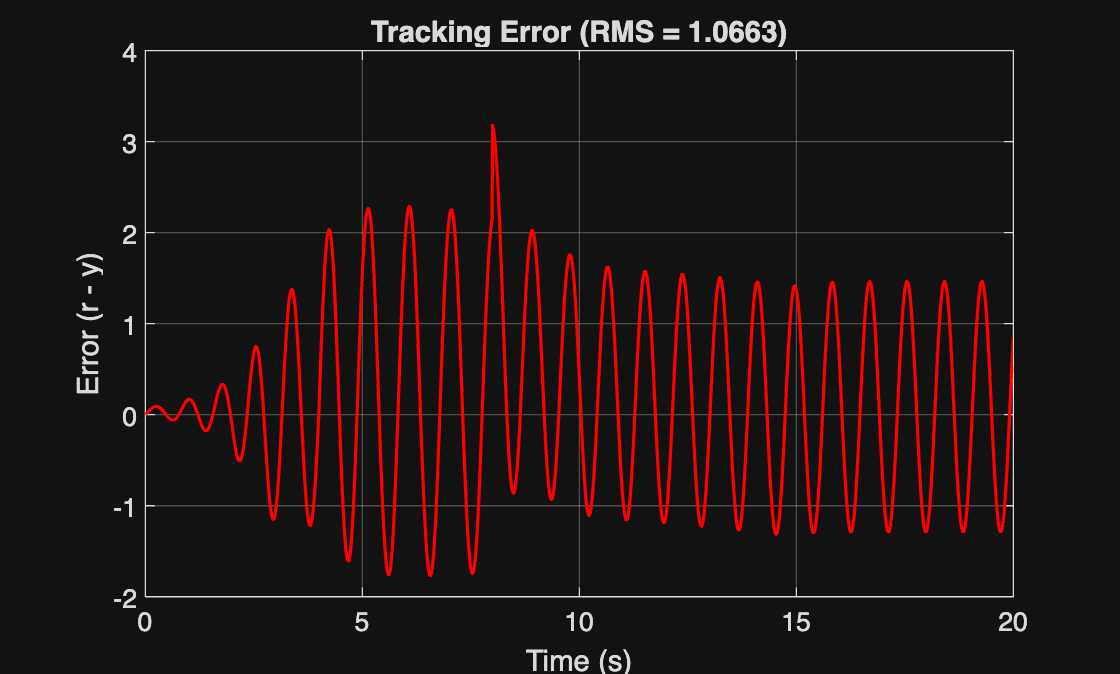

% Tracking Error 
figure;
plot(t, e_log, 'r', 'LineWidth', 1.2);
grid on;
title(['Tracking Error (RMS = ' num2str(rms_error, '%.4f') ')']);
xlabel('Time (s)');
ylabel('Error (r - y)');

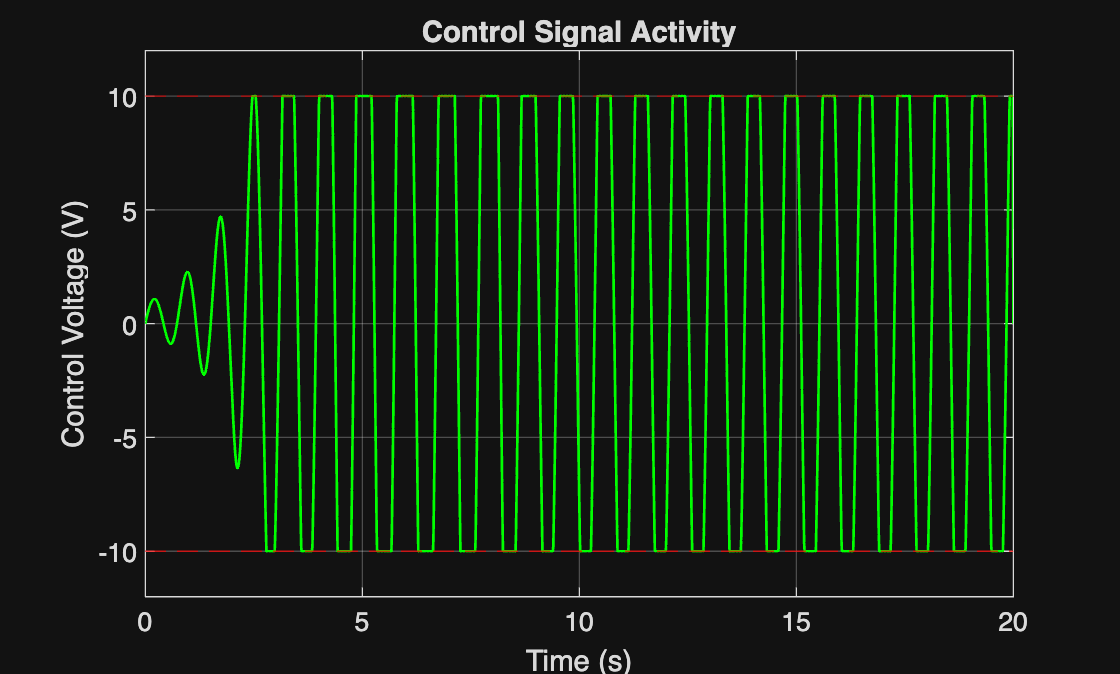

% Control Effort 
figure;
plot(t, u_log, 'g', 'LineWidth', 1.0);
grid on;
title('Control Signal Activity');
xlabel('Time (s)');
ylabel('Control Voltage (V)');
yline(10, 'r--'); yline(-10, 'r--'); % Show limits
ylim([-12 12]);

- The system tracks the ramp with a small, constant error (lag)

- For step and hold, the integrator term ensures the output settles exactly at the reference (zero steady-state error).

- For sinusoid, the derivative term effectively cancels the plant's natural lag by providing phase lead.

The control signal graph clearly shows the signals flattening at the 10V mark, therefore not crossing the actuator's limits.